%{
Name: Package delivery time Estimator
Author: Evan Scheuritzel
Version: 1.0
Purpose: Determine how long it takes to deliver packages over certain
distances.
Input: none
Output: Graph and Table containg Estimated times for delivery to occur
%}

clear
% distance 0-40 miles
d = 0:40;
% 2 miunte stop time, 15 minute package facility processing time
b = 2+15;
% average travel speed 30 mph or 0.5 miles per minute
m = 0.5;
T = m*d+b;

tableC = [d(6), T(6), "Short"
        d(11), T(11), "Short"
        d(16), T(16), "Short"
        d(21), T(21), "Medium"
        d(26), T(26), "Medium"
        d(31), T(31), "Medium"
        d(36), T(36), "Long"
        d(41), T(41), "Long"]

tableC = 8×3 string array
    "5"     "19.5"    "Short" 
    "10"    "22"      "Short" 
    "15"    "24.5"    "Short" 
    "20"    "27"      "Medium"
    "25"    "29.5"    "Medium"
    "30"    "32"      "Medium"
    "35"    "34.5"    "Long"  
    "40"    "37"      "Long"  


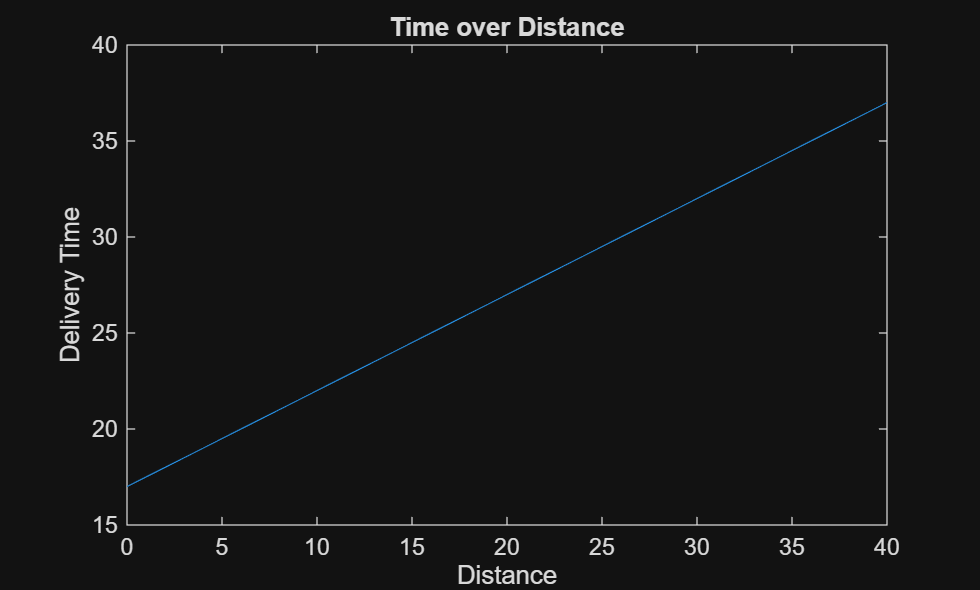


plot(d,T)
title('Time over Distance')
xlabel('Distance')
ylabel('Delivery Time')